%3.1 
syms x a b;
f = x * ( 1 + a / x) ^ x * sin(b / x);
L = limit(f, x, inf)

%3.2
syms x
f = (exp(x^3) - 1) / (1 - cos(sqrt(x - sin(x))));
L = limit(f, x, 0, 'right')

%3.3
syms t;
f = tan(t);
L1 = limit(f, t, pi/2, 'left')
L2 = limit(f, t, pi/2, 'right')

%3.4  (?)
syms x y a;
f = exp(-1/(x^2 + y^2))*sin(x)^2/x^2*(1 + 1/y^2)^(x+a^2*y^2);
L1 = limit(f, x, 1/sqrt(y))
L2 = limit(L1, y, inf)

%3.5
syms x;
f = sin(x) / (x^2 + 4*x + 3);
d = diff(f, x, 4)
d = collect(d, cos(x))
d = collect(d, sin(x))

%3.6
syms t;
y = sym('f(t)');
G = diff(t^2*sin(t)*y, t, 3)

%3.7
syms x y;
z = (x^2 - 2*x)*exp(-x^2-y^2-x*y);
zx = diff(z,x)
zy = diff(z,y)
[x,y]=meshgrid(-3:.2:3,-2:.2:2);
z=(x.^2-2*x).*exp(-x.^2-y.^2-x.*y);
surf(x,y,z)
shading interp
axis([-3 3 -2 2 -0.7 1.5])
axis square
grid off
%view(2)

%3.8
syms x y z;
f = sin(x^2*y)*exp(-x^2*y-z^2);
f1 = diff(f, x, 2);
f2 = diff(f1, y);
f3 = diff(f2, z);
f3 = simplify(f3);

%3.9
syms r theta phi
x = r*sin(theta)*cos(phi);
y = r*sin(theta)*sin(phi);
z = r*cos(theta);
J = jacobian([x; y; z], [r; theta; phi]);
J

%3.10
syms x y;
z = (x^2 - 2*x)*exp(-x^2-y^2-x*y);
H = jacobian(jacobian(z, [x,y]), [x,y]);
H

%3.11
syms x y;
z = (x^2 - 2*x)*exp(-x^2-y^2-x*y);
simplify(-diff(z, x)/diff(z,y)) %dy/dx = - (∂f/∂x) / (∂f/∂y)

%3.12
syms x y t;
y = sin(t)/(t+1)^3;
x = cos(t)/(t+1)^3;
ans_no_simplify = paradiff(y, x, t, 3);
[n, d] = numden(ans_no_simplify); %extract Numerator and Denominator
ans1 = simplify(n) / simplify(d)
ans2 = simplify(ans_no_simplify)

%3.13
syms x;
y = sin(x) / (x^2+4*x+3);
y1 = diff(y);
y0 = int(y1);
y0

%3.14
syms a x;
f = simplify(int(x^3*cos(a*x)^2,x))

%3.15
syms x a;
f = int(exp(-x^2/2));
vpa(f, 10)
int(x*sin(a*x^4)*exp(x^2/2),x)

%3.16
syms x a;
I1 = int(exp(-x^2/2), x, 0, 1.5)
vpa(I1, 32)
I2 = int(exp(-x^2/2), x, 0, inf)

%3.17
syms x t;
f = (-2*x^2+1)/(2*x^2-3*x+1)^2;
I = simplify(int(f, x, cos(t), exp(-2*t)))

%3.18
syms x y z;
f0 = -4*z*exp(-x^2*y-z^2)*(cos(x^2*y)-10*y*x^2*cos(x^2*y)+4*x^4*y^2*sin(x^2*y)+4*x^4*y^2*cos(x^2*y)-sin(x^2*y));
%f1 = simpily(int(int(int(f0,z),y),x^2)) %error: unable to integrate with respect to 'x^2'
f1 = simplify(int(int(int(int(f0,z),y),x),x))
f2 = simplify(int(int(int(int(f0,z),x),x),y))

%3.19
syms x y z;
f = int(int(int(4*x*z*exp(-x^2*y-z^2),x,0,2),y,0,pi),z,0,pi)
vpa(f, 60)

%3.20
syms x;
f = sin(x)/(x^2+4*x+3);
y1 = taylor(f,x,0,'Order',9) %Changed:Argument order changed
y2 = taylor(f,x,2,'Order',9) %Changed:Argument order changed
ez1=ezplot(f,[0,5]);
hold on;
ez2=ezplot(y1,[0,5]);
hold on;
ez3=ezplot(y2,[0,5]);
set(ez1,'color',[1 0 0])
set(ez2,'color',[0 1 0])
set(ez3,'color',[0 0 1])

%3.21
x0 = -2*pi:0.01:2*pi;
y0 = sin(x0);
plot(x0, y0);
axis([-2*pi,2*pi,-1.5,1.5]);
hold on;
syms x;
y = sin(x);
for n=8:2:16
    p = taylor(y,x,0,'Order',n);
    y1 = subs(p,x,x0);
    line(x0,y1);
end

%3.22
syms x y;
f = (x^2-2*x)*exp(-x^2-y^2-x*y);
%Changed:maple function is depreciated, and taylor function supports multiple variable now
F=taylor(f,[x,y],'Order',8); 
collect(F,x)

%3.23
%Textbook version
syms x;
hold off;
f = x*(x-pi)*(x-2*pi);
[A,B,F] = fseries(f,x,4,0,2*pi);
A
B
F
ezplot(f,[0,2*pi]);
hold on;
ezplot(F,[0,2*pi]);
%Fourier series using built-in fitting
hold off;
ezplot(f,[0,2*pi]);
hold on;
X = [0:pi/100:2*pi]';
Y = subs(f,x,X);
f = fit(X,Y,'fourier4')
plot(f,X,Y)
hold off;

%3.24
%Fourier series of square wave 

%Draw original function
syms x;
f = abs(x)/x;
X = -pi:pi/100:pi;
X = X(X~=0);        %Get rid of div-zero
X = [X,-eps,eps];   %Add eps for compensation
X = sort(X);        %Place eps to where it should be
Y = subs(f,x,X);
plot(X,Y);
hold on;
%Draw fourier fitting function
%BUG!
for p = 8:8
    [A,B,F] = fseries(f,x,p,-pi,pi);
    if p == 8
        F
        A
        B
    end
    ezplot(F,[-pi,pi]);
end
%Using built-in version
X = X';
Y = Y';
f = fit(X,Y,'fourier8')
plot(f,X,Y);
%Warning: axis must be excuated after the last plot function to be effective
axis([-4,4,-1.5,1.5]); 
hold off;

%3.25
%Sum of finite series
sum(sym(2).^[0:200]) %it's observed to be faster than statement below once
syms k;
symsum(2^k,0,200)

%3.26
%Sum of infinite series
syms n;
s = symsum(1/((3*n-2)*(3*n+1)),n,1,inf)

%3.27
%Sum of infinite series with variable
%Waring: form of answer is different from that on textbook
syms n x;
s = symsum(2/((2*n+1)*(2*x+1)^(2*n+1)),n,0,inf) %Warning: attention to the bracket matching
simplify(s)
w = s - log((x+1)/x);
vpa(subs(w,x,1),10)

%3.28
%Mix sum of series and limits
syms m n;
%limit(symsum(1/n,n,1,inf)-log(n),n,inf) %Error
limit(symsum(1/m,m,1,n)-log(n),n,inf)

%3.29
%Product of series
%Changed
syms n;
symprod(1-2/(n*(n+1)),n,2,inf)

%3.30
%Line integral of a scalar field
syms t;
syms a positive;
x = a*cos(t);
y = a*sin(t);
z = a*t;
f = z^2/(x^2+y^2);
lineint1(f,x,y,z,t)

%3.31
%Line integral of a scalar field
syms t;
x = t;
y = t;
z = 0;
f = x^2 + y^2;
p1 = -lineint1(f,x,y,z,t,1,0)
y = t^2;
%Error!!!
%Not have update f
%%%
f = x^2 + y^2;
%%%
p2 = lineint1(f,x,y,z,t,0,1)
p  = p1 + p2

%3.32
%Line integral of a vector field
syms t;
syms a positive;
x = a*cos(t);
y = a*sin(t);
z = 0;
P =  (x+y)/(x^2+y^2);
Q = -(x-y)/(x^2+y^2);
R = 0;
I = lineint2(P,Q,R,x,y,z,t,2*pi,0)

%3.33
%Line integral of a vector field
syms t;
syms a positive;
x = t;
y = t^2;
z = 0;
P = (x^2-2*x*y);
Q = (y^2-2*x*y);
R = 0;
I = lineint2(P,Q,R,x,y,z,t,-1,1)

%3.34
%Surface integral of a scalar field
syms x y;
syms a positive;
z = a - x - y;
f = x*y*z;
surfaceint1(f,z,x,0,a-y,y,0,a)

%3.35
%Surface integral of a scalar field
syms u v;
syms a positive;
x = u*cos(v);
y = u*sin(v);
z = v;
f = x^2*y + z*y^2;
surfaceint1(f,x,y,z,u,0,a,v,0,2*pi)

%3.36
%Surface integral of a vector field
syms u v;
%Warning: this example proves the domain of modifier "positive" is one whole line
syms a b c positive;
x = a*sin(u)*cos(v);
y = b*sin(u)*sin(v);
z = c*cos(u);
surfaceint2(0,0,x*y+z,x,y,z,u,0,pi,v,0,2*pi)

%3.37
%Numeric diff
syms x;
X = 0:0.05:pi;
y = sin(x)/(x^2+4*x+3);
%Warning: must do manual syms->double conversion in  this step because Y will be passed to our diff_ctr function
Y = double(subs(y,x,X));        
dy1 = diff(y);                  %Analytical solution
dy1_value = subs(dy1,x,X);      %Accurate result
[dy1_,x_] = diff_ctr(Y,0.05,1);
plot(X,dy1_value,x_,dy1_);

%3.38
%Gradient of two-variable function
hold off;
[x,y]=meshgrid(-3:.05:3,-2.05:2);
syms sx sy;
f = (sx^2-2*sx)*exp(-sx^2-sy^2-sx*sy)

$$f = -{\mathrm{e}}^{-{\mathrm{sx}}^{2}-\mathrm{sx}\,\mathrm{sy}-{\mathrm{sy}}^{2}}\,\left(2\,\mathrm{sx}-{\mathrm{sx}}^{2}\right)$$

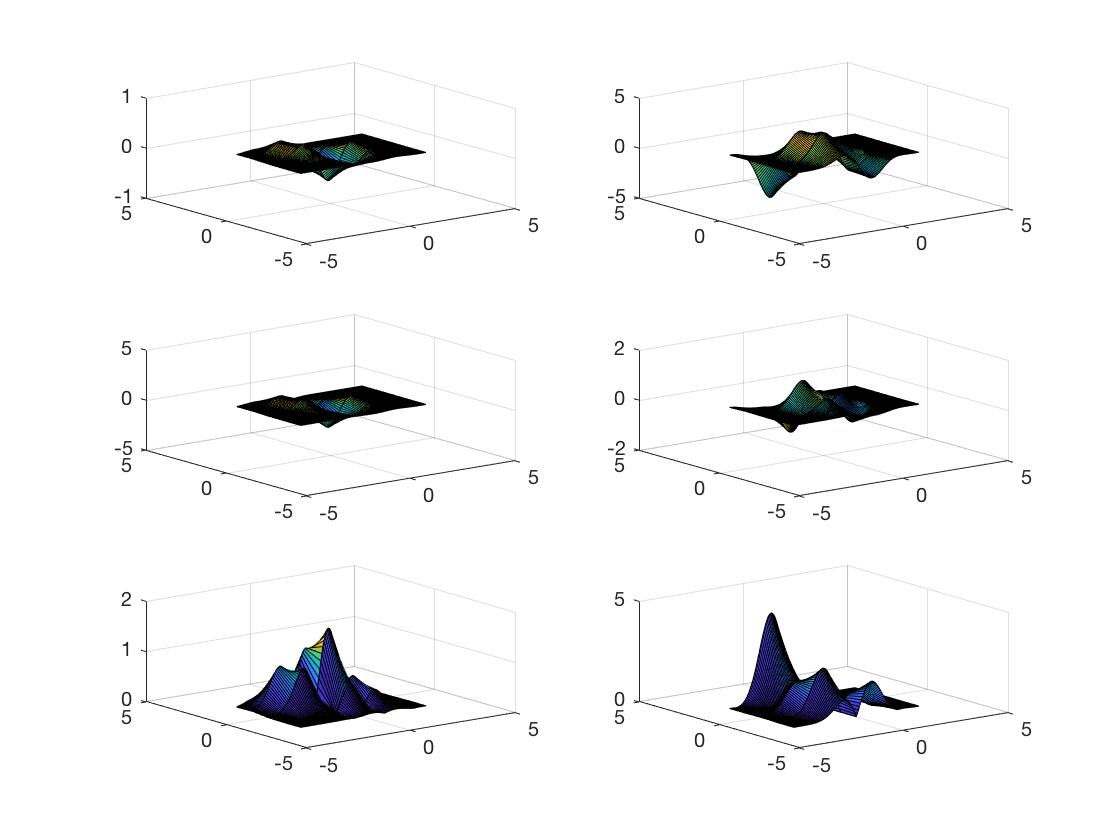

z = double(subs(f,{sx,sy},{x,y}));
[fx,fy]=gradient(z);
fx=fx/0.2;
fy=fy/0.2;
subplot(321);
surf(x,y,fx);
subplot(322);
surf(x,y,fy);
zx = diff(f,sx);
zy = diff(f,sy);
subplot(323);
fx_acc = double(subs(zx,{sx,sy},{x,y}));
surf(x,y,fx_acc);
subplot(324);
fy_acc = double(subs(zy,{sx,sy},{x,y}));
surf(x,y,fy_acc);
subplot(325);
surf(x,y,abs(fx_acc-fx));
subplot(326);
surf(x,y,abs(fy_acc-fy));